# Frequency Domain Analysis

 This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

## Frequency response of a transfer function

A transfer function with complex poles has undamped natural frequencies given by the magnitudes of the poles: $\omega_n = |p|$. If an input force drives a system at or near its natural frequency, the solution can grow rapidly in magnitude.

 **Exercise. **In this exercise, you will visually analyze a mass-spring-damper's response to sinusoidal inputs $u = \sin( \omega_u t )$ with various frequencies $\omega_u$.

      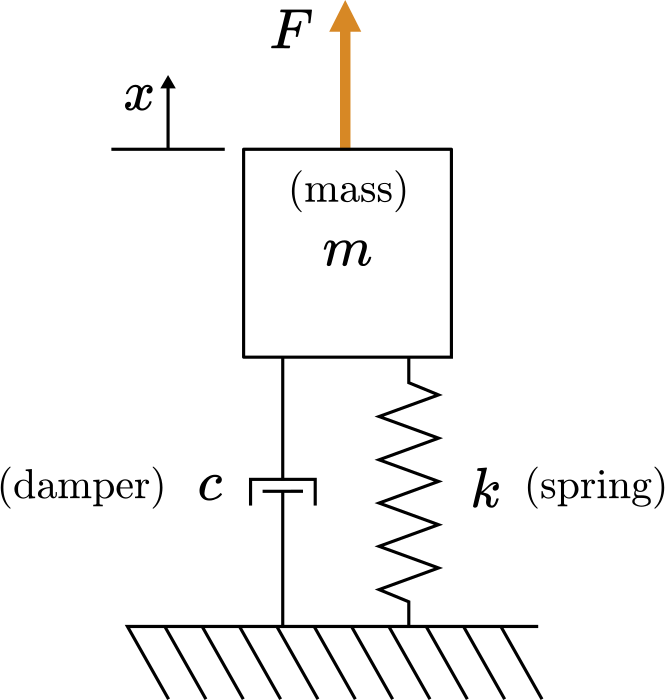

        *Mass-spring-damper diagram*

Consider the mass-spring-damper transfer function with $m = 1$, $c = 0.1$, and $k = 1$:

    
$$\frac{X(s)}{U(s)} = \frac{1}{ s^2 + 0.1 s + 1}$$


**(a) **What are the poles of the transfer function?

% Write your code here

% Record your answer in p
p = NaN;

check1(p) % Checks your answer

**(b)** What is the undamped natural frequency of the function in rad/s?

% Write your code here

% Record your answer in freq
freq = NaN;

check2(freq) % Checks your answer

**(c)** The simulation below drives the function $G$ with an input function $U = \sin( \omega_u t )$ which has a frequency of $\omega_u$ rad/s. The input and output signals are plotted by simulating the response with the `lsim` function.

- What driving frequency $\omega_u$ produces the response with the greatest magnitude?

- How long does it take for the response to reach a steady state?

- Does the frequency of the steady-state waveform match the frequency of the input waveform?

- Is the output $x(t)$in or out of phase with the input $u(t)$? Does this depend on $\omega_u$?

omegau = 0.5; % Frequency of the forcing [rad/s]
figure
t = linspace(0,100,1e3);   % Time variable array
u = sin(omegau*t);         % Forcing function (as an array)
G = tf([0 0 1],[1 0.1 1]); % The transfer function
lsim(G,u,t)                % Run simulation
axis([0 100 -20 20])       % Adjust the axis limits
ylabel("x [m]")

### Constructing a Bode plot

In general, the frequency response of a transfer function is analyzed by providing input sinusoids with different frequencies and identifying how the magnitude and phase of the steady output changes.

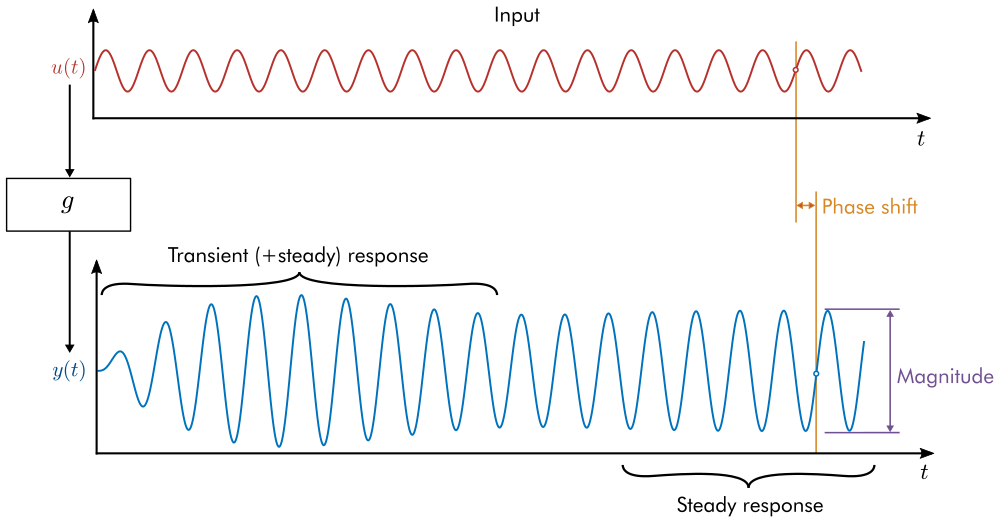

*The steady response of a linear time-invariant system to a sine input will be a sine wave with the same frequency as the input. The response sine wave undergoes a phase shift and a change in magnitude that depend on the frequency of the input sine wave. This plot only shows the response to a single frequency. *

The frequency-domain analysis is often shown in a **Bode plot**. The Bode plot is constructed by plotting the phase shift and magnitude at varied input frequencies, capturing the system's response to many different frequencies in a single diagram.

    **Activity. **In this activity, you will construct the Bode plot for the mass-spring-damper displacement transfer function:

      
$$\frac{X(s)}{U(s)} = \frac{1}{ s^2 + 0.1 s + 1}$$


For each sinusoidal input $u(t) = \sin(\omega_u t)$ the output $x(t)$ shows a transient behavior and a steady state behavior. The steady-state behavior is a sine wave with magnitude $M$ and phase $\phi$: 

    
$$x_{steady}(t) = M \sin (\omega_u t + \phi )$$


The Bode plot is generated by plotting the magnitude and phase of the steady-state output against the input frequency, $\omega_u$. The magnitude and frequency are plotted on logarithmic axes. 

**Part 1. **Start by running this section to create the figure and the transfer function `G`.

G = tf([0 0 1],[1 0.1 1]); % The transfer function
fh = figure("Position",[1 1 1500 700]); % Create figure with handle fh
 

**Part 2.**

- Set a frequency `omegau` for the input sine wave. 

- Observe the phase and magnitude of the steady response. Observe that the phase and magnitude are automatically added as a new point on the Bode diagram.

- Repeat until the Bode diagram figure is populated.

omegau = 3; % Input frequency in rads/second
omegau = omegau; % If you prefer to type values rather than use the slider, do so here.
createBodePlot(fh,omegau,G);

**  Reflect.** 

- At which frequency is the most significant change in magnitude observed?

- At which frequencies are the oscillations attenuated?

- How does the phase of the response change between low and high frequency input signals?

 **Exercise.** Consider the transfer function used in the previous activity:

        
$$G(s) = \frac{1}{ s^2 + 0.1 s + 1}$$


Generate the Bode diagram using the [`Bode`](https://www.mathworks.com/help/control/ref/lti.bode.html) function. Use [`grid on`](https://www.mathworks.com/help/matlab/ref/grid.html) to turn on the grid.

figure
% Create your Bode plot here



**  Reflect.** 

- How does this Bode diagram differ from the one created in the previous activity?

- How do you think the phase and magnitude of the response are computed "under the hood?"

## Numerical evaluation of the frequency response

It is not necessary to compute the time-domain response to create a Bode plot as done in the activity above. The activity only illustrates the principle behind the Bode plot. In practice, the frequency response can be computed entirely in the $s$-domain. This is accomplished by:

- generating the *complex transfer function* by making the substitution $s = i \omega$

- evaluating the complex transfer function at various frequencies

- computing the magnitude and phase of the result

 **Example.** Generate a Bode plot for the mass-spring-damper system:

        
$$G(s) = \frac{1}{ s^2 + 0.1 s + 1}$$


by evaluating the complex transfer function.

**Solution. **

The complex transfer function is created by setting $s = i \omega$:

        
$$G(i \omega) = \frac{1}{  (i\omega)^2 + 0.1(i  \omega) + 1} = \frac{1}{ - \omega^2 + 0.1 i  \omega + 1}$$


Numerically evaluating the complex transfer function for many frequencies $\omega$ can be accomplished using an array of frequencies.

omega = linspace(0.1,10,500);                   % An array of frequencies
Giomega = 1./(-omega.^2 + 0.1*1i*omega + 1)     % Complex transfer function evaluated at many frequencies

The magnitude and phase of complex transfer function values can be computed directly on the arrays.

M = abs(Giomega);       % The magnitude of the complex number
Mdb = 20*log10(M)       % Magnitude in dB
phi = angle(Giomega);   % Phase angle in radians
phiDeg = phi*180/pi     % Phase angle in degrees

The first panel in the Bode plot is constructed by graphing the magnitude in dB against the input frequencies, $\omega$.

figure
semilogx(omega,Mdb)
xlabel("Frequency (rad/s)")
ylabel("Magnitude (dB)")

The second panel is constructed by graphing the phase in degrees against the input frequencies, $\omega$.

figure
semilogx(omega,phiDeg)
xlabel("Frequency (rad/s)")
ylabel("Phase (degrees)")

 **Exercise.** In this exercise, you will analyze the transfer function

        
$$H(s) = \frac{1}{ s^2 + 9}$$


This transfer function corresponds to a mass-spring system with parameters $m = 1$ and $k = 3$. 

**(a) **What are the natural frequencies of $H$ in rad/s? 

% Write your code here

% Record your answer in omegan
omegan = NaN

check3(omegan)

**(b) ** Generate the Bode plot for $H$ using the `bode` function.

% Write your code here



**(c)** Write the expression for the complex transfer function by making the substitution $s = i \omega$. What is the value of the complex transfer function for $\omega = 0.5$? 

% Record your answer in Hcomplex
Hcomplex = NaN;

check4(Hcomplex) % Checks your answer

**(d) **What are the magnitude (in dB) and phase (in degrees) of the transfer function for $\omega = 0.5$? Can you identify this point on the Bode plot?

- Use the definition $y_{[dB]} = 20 \log_{10}(y)$.

MdB = NaN; % Calculate the magnitude in dB here
phase = NaN; % Calculate the phase in degrees here
check5(MdB)  % Checks your answer
check6(phase) % Checks your answer

**(d)** What is the value of the complex transfer function at the natural frequency computed in part **(a)**? 

% Record your answer in Hcomplex
Hcomplex = NaN;

check7(Hcomplex) % Checks your answer

**(e) **Use the [`lsim`](https://www.mathworks.com/help/control/ref/lti.lsim.html) function to compute and plot the time-domain response of $H$ to a sinusoidal input function

     
$$u(t) = \sin( \omega_n t)$$


where $\omega_n$ is the natural frequency you computed in **(a)**. Simulate until a final time of 100 seconds.

% Write your code here



**  Reflect.** 

- What happens to the magnitude of the response as $t \to \infty$?

- Physically, what is happening in the mass-spring system driven at its natural frequency?

- Are the values of the complex transfer function meaningful at this frequency?

## Buck converter analysis

In an electric vehicle, the battery must power high voltage loads, like the DC motor (~600V) and low voltage loads, like the headlights (~12V). The battery bank will typically produce voltages in the range required by the DC motor. So how do you efficiently reduce the voltage so that it can power the low voltage systems?

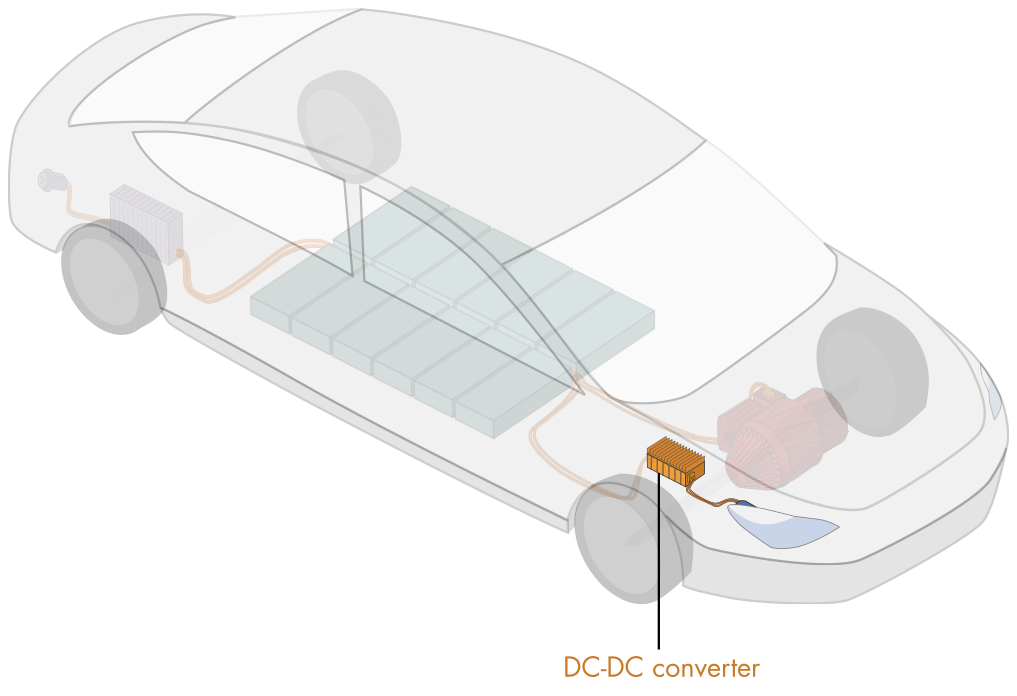

*Simplified electric vehicle schematic*

An obvious answer to reducing voltage is to connect a resistor in series with the load. This solution is inefficient, as the resistor gives off dissipated energy as heat. A much more practical solution is a switching buck converter. A switching buck converter typically uses a MOSFET (metal-oxide-semiconductor field-effect transistor) to switch the power supply on and off at a high frequency. The average of the resulting voltage will be lower than the original, and the mean value of the output voltage can be changed by altering the duty cycle.

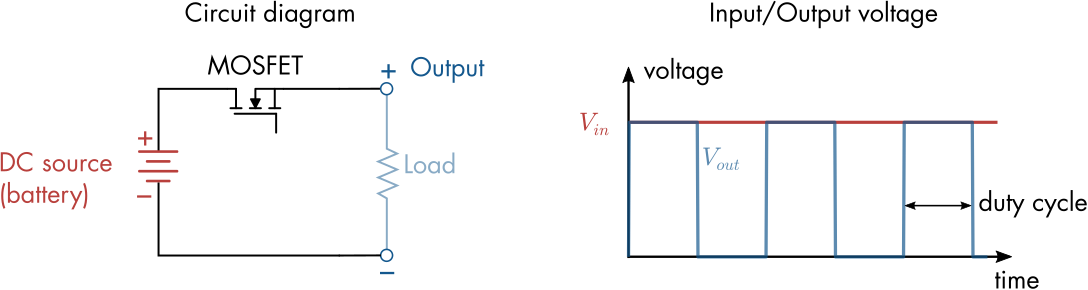

*A simple switching circuit. The DC input *$V_{in}$ is constant. The output voltage $V_{out}$ depends on the switching characteristics of the MOSFET.

In the plot above, the duty cycle is $d = 0.5$, implying that the average output voltage is half the input voltage: $\bar{V}_{out} = 0.5 V_{in}$. A shorter duty cycle will further reduce the mean voltage. The issue with this switching device is that the output is not a DC source: it contains harmonics at the switching frequency. These harmonics can produce undesirable effects in the downstream load. Buck converters typically have a filter to attenuate the switching harmonics.

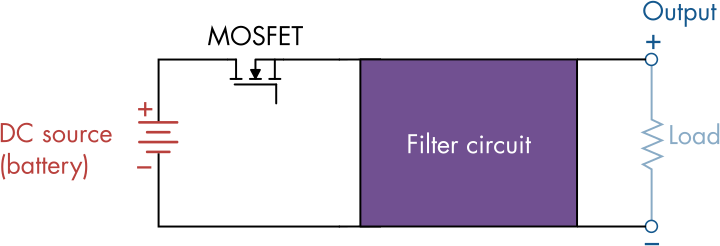

*A filter is included in buck converters to attenuate switching harmonics.*

In this section, you will analyze filter circuits using transfer functions. All of the components are treated as ideal (lossless).

### Inductor filter

An inductor filters out switching harmonics by storing and releasing energy during the switching cycle.

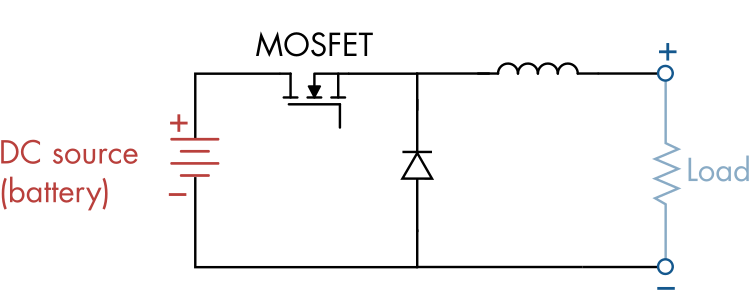

*An inductor filter. The diode is required so that current can flow when the MOSFET is off.*

When the MOSFET is on, current flows from the battery charging the inductor and powering the load. When the MOSFET is off, energy stored in the inductor is released, powering the load.

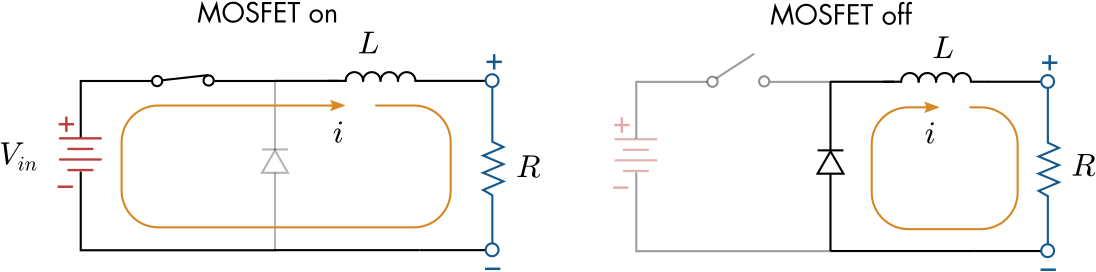

*Cycle of a switching circuit with an inductor filter. When the MOSFET is off, the inductor powers the load.*

The filter circuit differential equations are derived using Kirchhoff's voltage law, which states that the voltage around any closed loop of the circuit must be zero. While these two states can be thought of as separate circuits, they can be modeled by a single application of Kirchhoff's voltage law if the potential differences across the diode, voltage source, and switch are all modeled together by a single function, $u(t)$. In this case, $u(t)$ is a square wave that switches between the battery voltage $V_{in}$ and zero (the voltage drop across an ideal diode). 

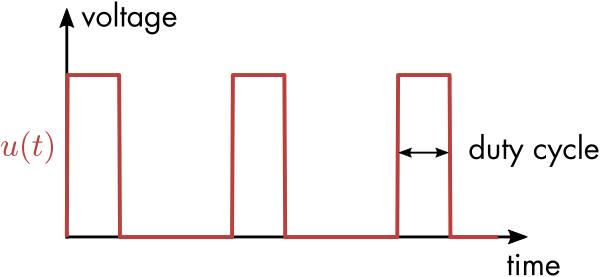

*The input function *$u(t)$* models the potential differences from the voltage source, MOSFET, and diode in one function.*

With this definition, Kirchhoff's voltage law implies:

    
$$u(t) - L \frac{di}{dt} - iR = 0$$


 **Exercise.** Solve for the transfer function of the inductor filter circuit with input $u(t)$, output $i(t)$, and zero initial conditions. 

syms L R s
% Record your expression here in UoverI in terms of the symbolic variables
UoverI = NaN;

check8(UoverI) % Checks your result

In this analysis, the voltage across the resistor is the variable of interest rather than the current. The current is related to the voltage across the resistor $V$ by Ohm's law: $V(s) = R I(s)$. This implies the voltage transfer function is:

    
$$\frac{V(s)}{U(s)} = \frac{R}{L s + R}$$


 **Exercise. **In this exercise, you will analyze the transfer function

    
$$G(s) = \frac{V(s)}{U(s)} = \frac{R}{L s + R}$$


that relates the output voltage (i.e., across the resistor) to the switched voltage input $u(t)$.

**(a) ** Suppose that resistance of the load $R = 5 \Omega$ and the inductance is $L = 10$$\mu$H. Define the transfer function $G$ in MATLAB using the `tf` function. What are the poles of $G$?

% Write your code here

% Record the poles of G in p
p = NaN;
check9(p) % Checks your result

**(b) **Generate the Bode plot for `G`.

% Write your code here


**(c)** At an input frequency of 500 kHz, how much will the signal be attenuated (in dB)? 

**Hint**: Evaluate the magnitude of the complex transfer function.

% Write your code here


% Record the value of the attenuation in "attenuation" 
attenuation = NaN 
check10(attenuation)

**(d) **Based on the value that you computed in **(c)**, do you think that an input voltage switching at a frequency of 500 kHz will produce a steady output voltage? To find out, simulate the response of the system to an input square wave with a duty cycle of 60% and an input voltage $V_{in} = 48$V using the [`lsim`](https://www.mathworks.com/help/control/ref/lti.lsim.html) function. The input function $u(t)$ and time variable $t$ have already been computed for you.

% The input function u(t)
f = 500e3;                              % Switching frequency [Hz]
d = 0.6;                                % Duty cycle in [0,1]
cycles = 10;                            % Number of cycles to simulate
M = 48;                                 % Magnitude [V]
t = linspace(0,cycles/f,100*cycles);    % time variable array
u = switchedInput(t,f,d,M);             % The input function u(t)

% Simulate the system here


**(e)** You can evaluate how well the filter performed by computing the *ripple*. The ripple is the difference between peak and trough values of the voltage once it has reached a steady state. What is the voltage ripple in this system? You can estimate it by using the data tip tool in the plot above.

% Record your answer here in Vripple
Vripple = NaN;

check11(Vripple)

**  Reflect.** 

- Try increasing the inductance in the system. Does the Bode plot change to indicate greater or less attenuation of the 500 kHz signal? Does the voltage ripple change?

- If increasing the inductance diminishes ripple, why is the largest inductance not always selected? What other considerations might affect the choice?

- This type of filter is commonly referred to as a "low-pass" filter. Where is this name reflected in the Bode plot?

### LC filter

A single inductor is not typically used to filter a buck converter. A more typical setup includes an inductor and a capacitor.

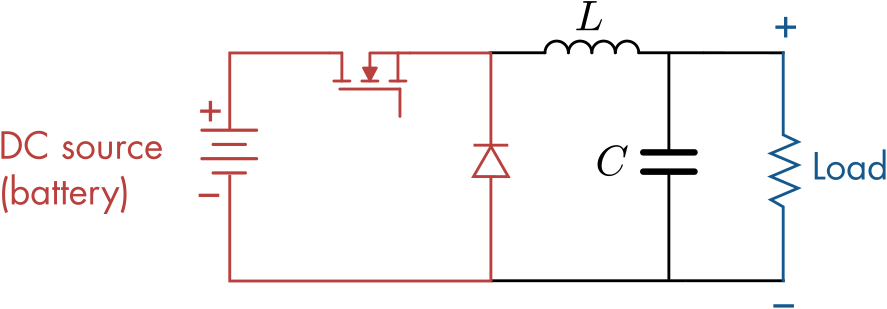

*Buck converter with an inductor and capacitor (LC) filter.*

The differential equations that govern this circuit can be derived by applying Kirchhoff's voltage law twice. 

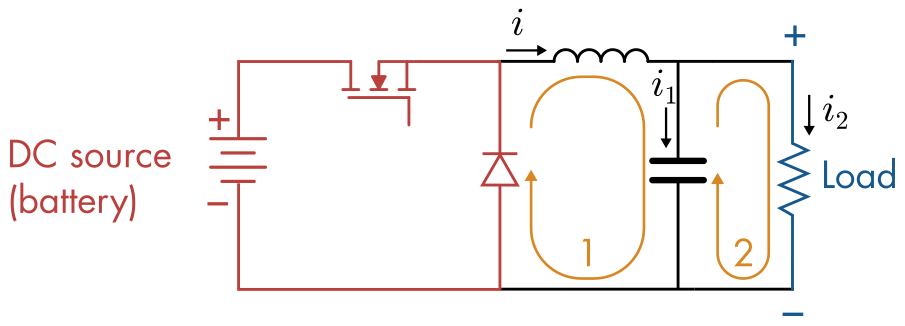

*Loops and assigned current directions for the application of Kirchhoff's laws.*

The potential differences resulting from the DC source, MOSFET, and diode are all captured in the input function, $u(t)$. Applying Kirchhoff's voltage law around the two closed loops gives:

    (1) $u(t) - L \frac{di}{dt} - i_2 R = 0$                   (2)  $\frac{1}{C} \int  i_1 d\tau - i_2 R = 0$

Taking the Laplace transform yields

    (1) $U(s) - Ls I(s) - R I_2(s) = 0$         (2) $\frac{1}{Cs} I_1(s) - R I_2(s) = 0$

Kirchhoff's current law implies that $I  = I_1 + I_2$. So (1) can be rewritten as

    
$$U - Ls(I_1 + I_2) - R I_2 = 0$$


The variable of interest is $V(s)$, the Laplace transform of the voltage across load. By Ohm's law, the voltage drop across the resistor is $V(s) = R I_2(s)$. Substituting this expression and (2) into (1) and simplifying yields

    
$$U - Ls(CsV + V/R) - V = 0$$


Rearrange to find the transfer function $V/U$:

    
$$\frac{V}{U} = \frac{R}{LCRs^2 + Ls + R$$


Notice that in the case where $C = 0$, this reduces to the transfer function for the inductor only.

 **Exercise. **In this exercise, you will analyze the buck converter with an LC filter using its transfer function

    
$$H(s) = \frac{R}{LCRs^2 + Ls + R$$


**(a)** Define the transfer function using `tf` with $L = 1$$\mu$H, $C = 5$$\mu$F, and $R = 5 \Omega$. 

% Write your code here

**(b)** What is the natural frequency of $H$ in Hz?

% Write your code here

% Record your answer in wnHz 
wnHz = NaN

check12(wnHz)

**(c)** Plot the Bode diagram for $H$.

- What switching frequencies will produce the desired result (i.e., a steady DC voltage source)?

- What frequencies result in the opposite of the desired response?

% Write your code here



**(d)** Compute the system's response to a swtiching frequency of 750 kHz. You can use the array `u` as the input after setting the switching frequency `f`.

- What is the voltage ripple (the difference between the peak and trough of the voltage in steady state)?

- How long does it take to reach steady state? You may need to increase the number of cycles.

f = 100e3; % Set this                   % Switching frequency [Hz]
d = 0.6;                                % Duty cycle in [0,1]
cycles = 400;                           % Number of cycles to simulate
M = 48;                                 % Magnitude [V]
t = linspace(0,cycles/f,100*cycles);    % time variable array
u = switchedInput(t,f,d,M);             % The input function u(t)

figure("Position",[1 1 1200 400])
% Simulate the system here


**(e)** Compute the response of the system if the input switching frequency is the natural frequency of $H$. What is the voltage ripple at this frequency?

f = 100e3; % Set this                   % Switching frequency [Hz]
d = 0.6;                                % Duty cycle in [0,1]
cycles = 400;                           % Number of cycles to simulate
M = 48;                                 % Magnitude [V]
t = linspace(0,cycles/f,100*cycles);    % time variable array
u = switchedInput(t,f,d,M);             % The input function u(t)

figure("Position",[1 1 1200 400])
% Simulate the system here


  **  Reflect.** 

- Does the LC filter perform better than the L filter? What are the pros and cons of each?

- Try increasing the switching frequency. How does the response change? Does this improve the response?

- Try increasing the capacitance $C$ and examine the Bode plot and response curves. Does increasing $C$ improve the performance of the filter?

## 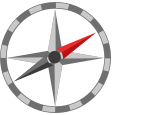**Further exploration**

- Review Bode plots in the MATLAB Tech Talk series: [Understanding Bode Plots](https://www.mathworks.com/videos/series/understanding-bode-plots-95146.html)

- Learn more about frequency domain responses in the MATLAB Tech Talk: [Control Systems in Practice, Part 10: Nichols Chart, Nyquist Plot, and Bode Plot](https://www.mathworks.com/videos/control-systems-in-practice-part-10-nichols-chart-nyquist-diagram-and-bode-plot-1607596350472.html)

- Continue exploring Bode plots in Brian Douglas' videos: [Bode Plots, Introduction](https://www.youtube.com/watch?v=_eh1conN6YM&t=2s) and [Bode Plots by Hand: Real Constants](https://www.youtube.com/watch?v=CSAp9ooQRT0).

- You can also use transfer functions in Simulink models. Check out [this documentation page](https://www.mathworks.com/help/simulink/slref/transferfcn.html) to learn how.

**Helper functions**

**Math functions**

function u = switchedInput(t,f,d,M)
    % Generates a shifted square wave with a magnitude specified by M, 
    % a duty cycle d, and frequency f
    u = M*(mod(t,1/f) < d/f);
end

**Plots**

function createBodePlot(fh,omegau,G)
% This function creates a bode plot systematically by adding 
% individual points that correspond to inputs with frequency omegau
%
% This function is for illustrative purposes only.
%
    figure(fh)
    colors = [lines(1);0.7176 0.1922 0.1725];
    
    % Compute the transfer function
    t = linspace(0,100,1e3);
    ts0 = 200 - rem(200,2*pi/omegau);
    t2 = linspace(ts0,ts0+25,1e3);
    u = sin(omegau*t);
    y = lsim(G,u,t);
    
    % Compute the magnitude/phase of the response
    response = evalfr(G,1i*omegau);
    M = abs(response);
    phi = angle(response);
    shift = -phi/omegau;
    ysteady = M*sin(omegau*t2 + phi);
    u2 = sin(omegau*t2);
    ymax = 12;
    fs = 12;
    
    subplot(2,4,1:2)
    
    plot(t,u,"color",colors(2,:))
    hold on
    plot(t,y,"color",colors(1,:))
    hold off
    axis([t(1) t(end) -ymax ymax])
    xlabel("t [s]")
    ylabel("x [m]")
    title("Time domain response with \omega_u = " + num2str(omegau))
    legend("$u(t)$","$y(t)$","Interpreter","Latex")
    
    subplot(2,4,5:6)
    plot(t2,u2,"color",colors(2,:))
    hold on
    plot(t2,ysteady,"color",colors(1,:))
    plot(t2(round(end/2))*[1,1],[-M,M],"k-","Marker","_")
    
    text(t2(round(end/2)),M+1.2,"M = "+num2str(M,3),"HorizontalAlignment","center","fontsize",fs)
    phasePos = t2(1) + 2*pi/omegau + [0,shift];
    plot(phasePos(1)*[1 1],[-ymax ymax],":")
    plot(phasePos(2)*[1 1],[-ymax ymax],":")
    plot(phasePos,[0 0],"k-","Marker","|")
    text(mean(phasePos),-10,"-\phi / \omega_u = "+num2str(shift,3),"HorizontalAlignment","center","fontsize",fs)
    
    legend("$u(t)$","$y(t)$","Interpreter","Latex")
    
    hold off
    axis([t2(1) t2(end) -ymax ymax])
    xlabel("t [s]")
    ylabel("x [m]")
    title("steady response")

    subplot(2,4,3:4)
    h2 = findall(gca,"type","line");
    set(h2,"color","k","markersize",8)
    hold on
    plot(omegau,mag2db(M),".","linewidth",2,"color",colors(1,:),"markersize",20)
    hold off
    axis([0.1 10 -41 21])
    set(gca, "XScale", "log")
    title("Bode Diagram")
    ylabel("Magnitude (dB)")
    grid on

    subplot(2,4,7:8)
    h2 = findall(gca,"type","line");
    set(h2,"color","k","markersize",8)
    hold on
    plot(omegau,phi*180/pi,".","linewidth",2,"color",colors(1,:),"markersize",26)
    hold off
    axis([0.1 10 -181 1])
    set(gca, "XScale", "log","ytick",[-180 -135 -90 -45 0])
    xlabel("Frequency (rad/s)")
    ylabel("Phase (deg)")
    grid on
    
end

**Checks**

function isEqualCheck(userSubmission,correctAnswer)
% This function checks if two results are (nearly) equal and displays feedback
    if(class(correctAnswer) == "double")
         check = all(abs(userSubmission - correctAnswer) < 1e-5);
    else
         check = isequal(userSubmission,correctAnswer);
    end

    if( check )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

function check1(in)
    answer = pole(tf([0 0 1],[1 0.1 1]));
    isEqualCheck(in,answer)
end

function check2(in)
    answer = damp(tf([0 0 1],[1 0.1 1]));
    isEqualCheck(in,answer)
end

function check3(in)
    answer = damp(tf([0 0 1],[1 0 9]));
    isEqualCheck(in,answer)
end

function check4(in)
    answer = 1./(-0.5^2 + 9);
    isEqualCheck(in,answer)
end

function check5(in)
    Hcomplex = 1./(-0.5^2 + 9);
    answer = 20*log10(abs(Hcomplex));
    isEqualCheck(in,answer)
end

function check6(in)
    Hcomplex = 1./(-0.5^2 + 9);
    answer = angle(Hcomplex)*180/pi;
    isEqualCheck(in,answer)
end

function check7(in)
    answer = 1./(-3^2 + 9);
    isEqualCheck(sym(in),sym(answer))
end

function check8(in)
    syms L R s
    answer = 1/(L*s + R);
    isEqualCheck(simplify(sym(in)),simplify(answer))
end

function check9(in)
    answer = pole(tf([0 5],[10e-6 5]));
    isEqualCheck(in,answer)
end

function check10(in)
    R = 5;
    L = 10e-6;
    omega = 500e3*(2*pi);
    Gcomplex = R/(L*1i*omega + R);
    answer = 20*log10(abs(Gcomplex));
    isEqualCheck(in,answer)
end

function check11(in)
    answer = 33.92-22.95;
    check = abs(answer-in) < 2;
    if( check )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

function check12(in)
    L = 1e-6; % Henry
    C = 5e-6; % Farad 
    R = 5;    % Ohm
    H = tf([0 0 R],[L*C*R L R]);
    wn = damp(H);
    answer = wn/(2*pi);
    isEqualCheck(in,answer)
end